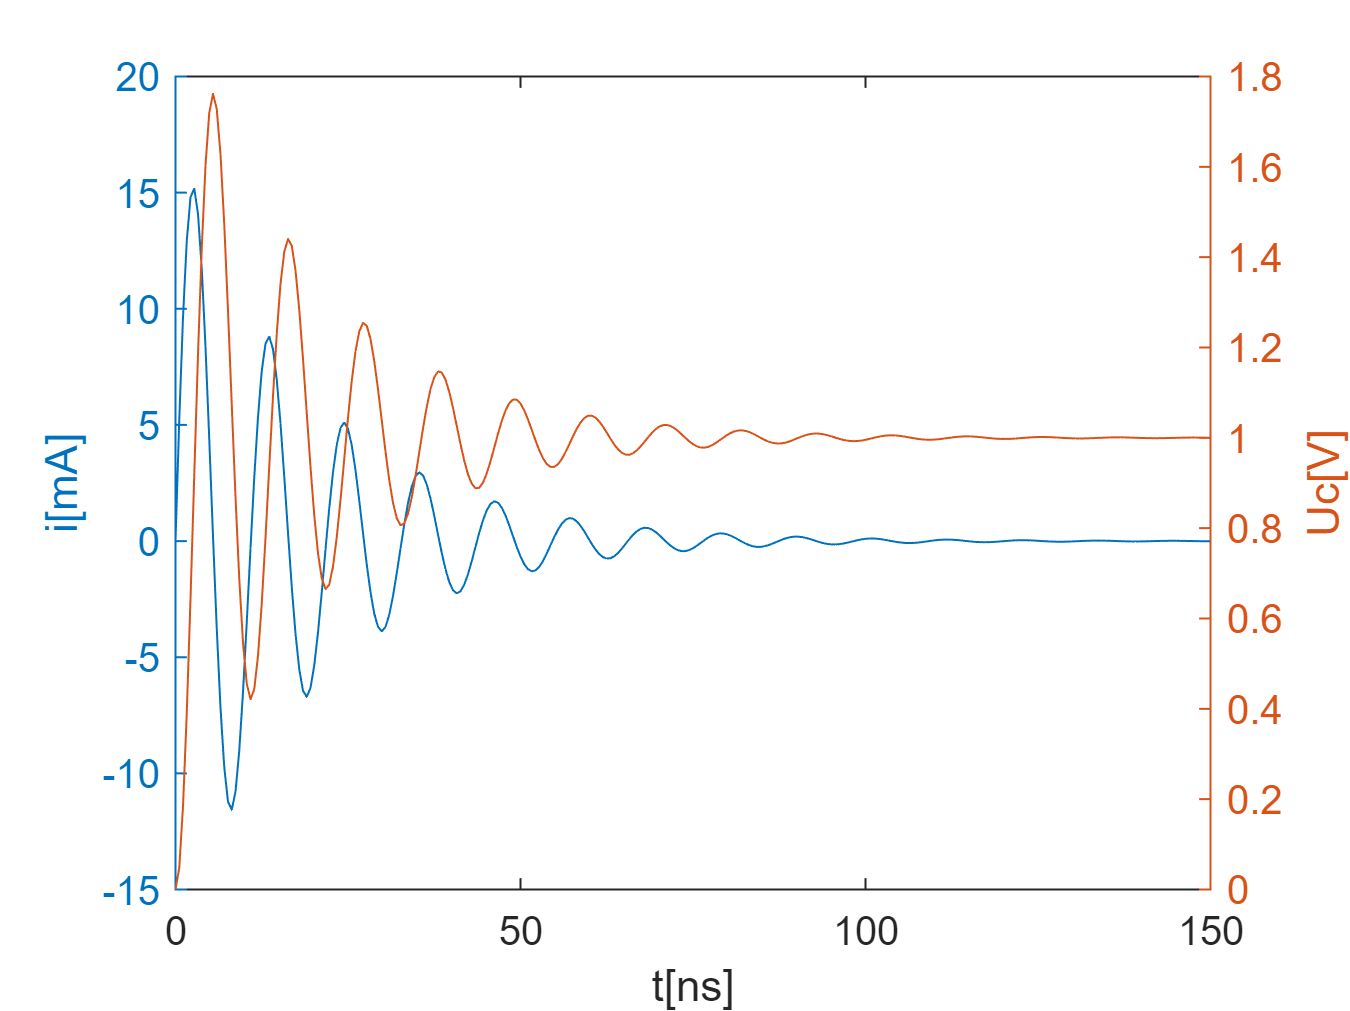

%exo exmple p30 de la théorie


clc;clear ;close all

R=10;
C=30e-12;
L =1.0000e-07;

AT=[-R/L -1/L;1/C 0];
BT=[1/L;0];
CT=[1 0; 0 1];
DT=0;

sys=ss(AT,BT,CT,DT,0);

[y,t]=step(sys,0.15e-6);


figure(1)
yyaxis left
plot(t*1e9,1e3*y(:,1))
ylabel('i[mA]')
yyaxis right
plot(t*1e9, y(:,2))
ylabel('Uc[V]')
xlabel('t[ns]')

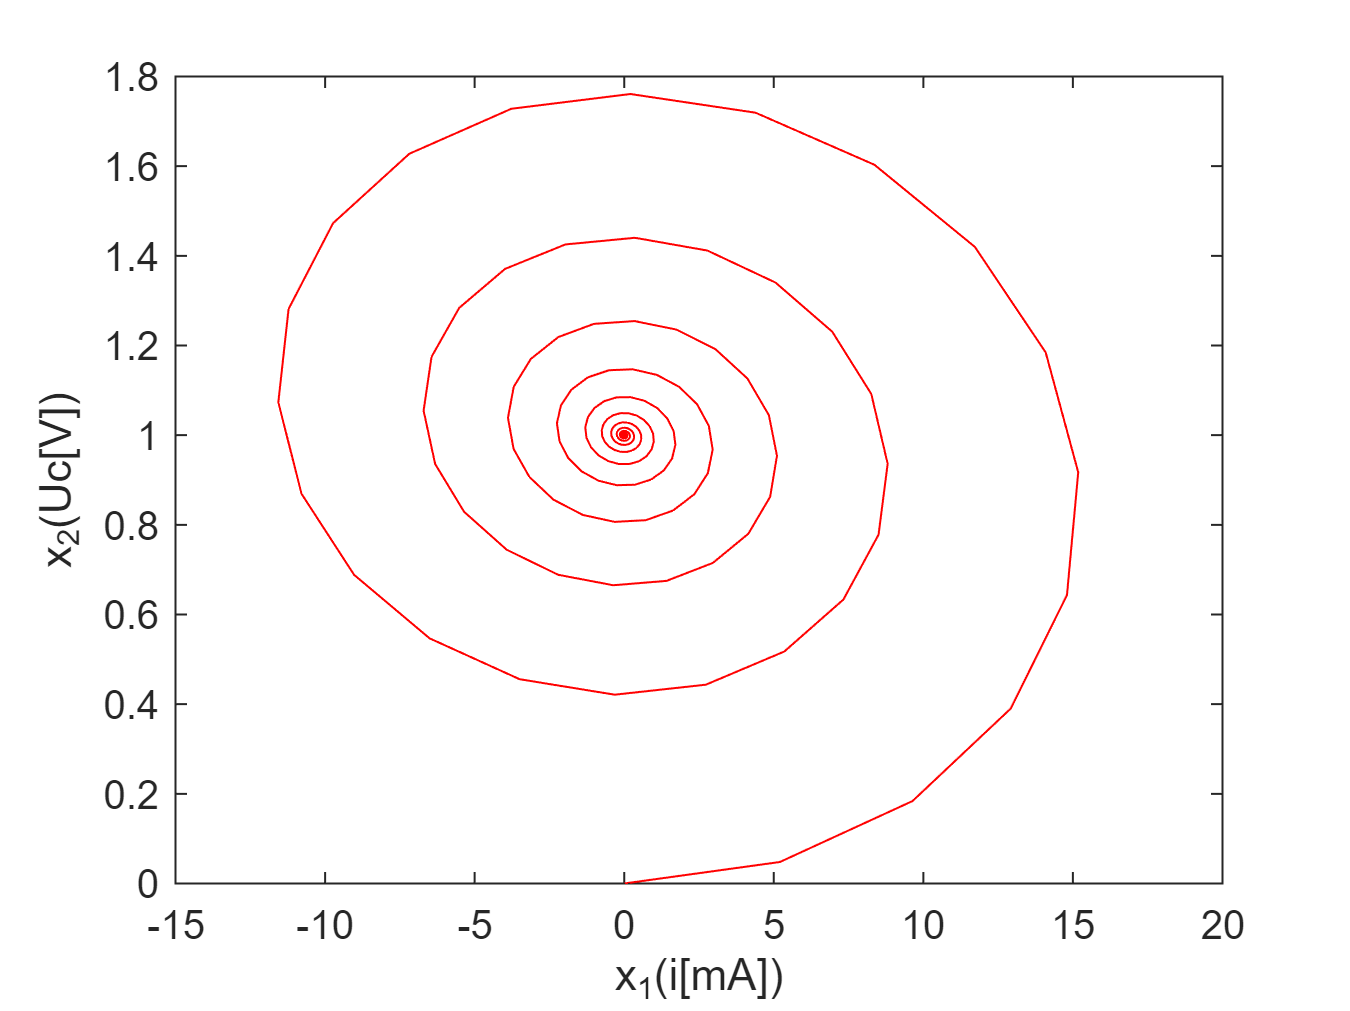


figure(2)
plot(1e3*y(:,1),y(:,2),'r')
xlabel('x_1(i[mA])')
ylabel('x_2(Uc[V])')



W0=1/(2*pi*(L*C)^0.5);
T0=2*pi/W0;
sim_T=2*T0;


%%ici on recherche les pôles youhouuu

syms L C R s

Am=[-R/L -1/L; 1/C 0];

I=[1 0 ; 0 1];

det(s*I-Am)         %pour chercher determinant matrice 

$$ans = \frac{C\,L\,s^{2}+C\,R\,s+1}{C\,L}$$


eig(Am)   %eigenvalue pour trouver S1 et S2

$$ans = \left(\begin{array}{c} -\frac{R+\sqrt{-\frac{4\,L-C\,R^{2}}{C}}}{2\,L}\\ -\frac{R-\sqrt{-\frac{4\,L-C\,R^{2}}{C}}}{2\,L} \end{array}\right)$$